% =========================================================================
% FUNKCJE DO ANALIZY FILTRÓW W OBWODZIE SZEREGOWYM RLC
% =========================================================================

%% Funkcja główna: Obliczanie transmitancji dla wszystkich typów filtrów
function [wielkosc, faza, parametry] = analyze_RLC_filters(R, L, C, w_czestotliwosci)
    % Funkcja oblicza moduł i fazę transmitancji dla filtrów RLC
    %
    % Parametry wejściowe: to bym zostawila bo spoko
    %   R - rezystancja [Ω]
    %   L - indukcyjność [H]
    %   C - pojemność [F]
    %   w_czestotliwosci - wektor częstotliwości [Hz]
    %
    % Parametry wyjściowe:
    %   wielkosc - struktura z modułami transmitancji [LP, HP, BP]
    %   faza - struktura z fazami transmitancji [LP, HP, BP] [stopnie]
    %   parametry - parametry charakterystyczne obwodu
    
    % Konwersja na pulsację kołową
    omega = 2 * pi * w_czestotliwosci;
    
    % Obliczanie parametrów charakterystycznych
    omega0 = 1 / sqrt(L * C);           % Częstotliwość rezonansowa [rad/s]
    f0 = omega0 / (2 * pi);             % Częstotliwość rezonansowa [Hz]
    Q = omega0 * L / R;                  % Dobroć obwodu
    szerokosc_pasma = R / L;                   % Szerokość pasma [rad/s]
    szerokosc_pasma_Hz = szerokosc_pasma / (2 * pi); % Szerokość pasma [Hz]
    
    % Zapisanie parametrów
    parametry.omega0 = omega0;
    parametry.f0 = f0;
    parametry.Q = Q;
    parametry.szerokosc_pasma = szerokosc_pasma;
    parametry.szerokosc_pasma_Hz = szerokosc_pasma_Hz;
    parametry.R = R;
    parametry.L = L;
    parametry.C = C;
    
    % Obliczanie transmitancji
    [H_LP, H_HP, H_BP] = obliczanie_transferu_funkcji(omega, R, L, C);
    
    % Moduły transmitancji
    wielkosc.LP = abs(H_LP);
    wielkosc.HP = abs(H_HP);
    wielkosc.BP = abs(H_BP);
    
    % Fazy transmitancji [stopnie]
    faza.LP = angle(H_LP) * 180 / pi;
    faza.HP = angle(H_HP) * 180 / pi;
    faza.BP = angle(H_BP) * 180 / pi;
end

%% Funkcja pomocnicza: Obliczanie transmitancji zespolonych
function [H_LP, H_HP, H_BP] = obliczanie_transferu_funkcji(omega, R, L, C)
    % Oblicza transmitancje zespolone dla trzech typów filtrów
    %
    % Parametry wejściowe:
    %   omega - wektor pulsacji kołowych [rad/s]
    %   R, L, C - parametry obwodu
    %
    % Parametry wyjściowe:
    %   H_LP, H_HP, H_BP - transmitancje zespolone
    
    % Wspólny mianownik dla wszystkich transmitancji
    denominator = 1 - omega.^2 * L * C + 1i * omega * R * C;
    
    % Filtr dolnoprzepustowy (kondensator)
    H_LP = 1 ./ denominator;
    
    % Filtr górnoprzepustowy (cewka)
    H_HP = (-omega.^2 * L * C) ./ denominator;
    
    % Filtr środkowoprzepustowy (rezystor)
    H_BP = (1i * omega * R * C) ./ denominator;
end

%% Funkcja do obliczania transmitancji w decybelach
function [mag_dB] = obliczanie_wielkosc_dB(wielkosc)
    % Konwertuje moduł transmitancji na decybele
    %
    % Parametry wejściowe:
    %   wielkosc - struktura z modułami transmitancji
    %
    % Parametry wyjściowe:
    %   mag_dB - struktura z modułami w decybelach
    
    mag_dB.LP = 20 * log10(wielkosc.LP);
    mag_dB.HP = 20 * log10(wielkosc.HP);
    mag_dB.BP = 20 * log10(wielkosc.BP);
end

%% Funkcja znajdująca częstotliwości -3dB
function [f_odciecia] = czestotliwosci_graniczne(w_czestotliwosci, wielkosc, f0)
    % Znajduje częstotliwości graniczne (-3dB) dla każdego filtru
    %
    % Parametry wejściowe:
    %   w_czestotliwosci - wektor częstotliwości [Hz]
    %   wielkosc - struktura z modułami transmitancji
    %   f0 - częstotliwość rezonansowa [Hz]
    %
    % Parametry wyjściowe:
    %   f_odciecia - struktura z częstotliwościami granicznymi
    
    % Konwersja na dB
    mag_dB = obliczanie_wielkosc_dB(wielkosc);
    
    % Dla filtru dolnoprzepustowego
    max_LP = max(mag_dB.LP);
    target_LP = max_LP - 3;
    idx_LP = find(mag_dB.LP <= target_LP, 1, 'first');
    f_odciecia.LP = w_czestotliwosci(idx_LP);
    
    % Dla filtru górnoprzepustowego
    max_HP = max(mag_dB.HP);
    target_HP = max_HP - 3;
    idx_HP = find(mag_dB.HP >= target_HP, 1, 'first');
    f_odciecia.HP = w_czestotliwosci(idx_HP);
    
    % Dla filtru środkowoprzepustowego
    max_BP = max(mag_dB.BP);
    target_BP = max_BP - 3;
    idx_dolny = find(w_czestotliwosci < f0 & mag_dB.BP >= target_BP, 1, 'first');
    idx_gorny = find(w_czestotliwosci > f0 & mag_dB.BP <= target_BP, 1, 'first');
    f_odciecia.BP_lower = w_czestotliwosci(idx_dolny);
    f_odciecia.BP_upper = w_czestotliwosci(idx_gorny);
    f_odciecia.BP_szerokosc_pasma = f_odciecia.BP_upper - f_odciecia.BP_lower;
end

%% Funkcja wizualizacji wyników
function wykres_charakterystyki(w_czestotliwosci, wielkosc, faza, parametry, filter_type)
    % Rysuje charakterystyki amplitudowe i fazowe
    %
    % Parametry wejściowe:
    %   w_czestotliwosci - wektor częstotliwości [Hz]
    %   wielkosc, faza - struktury z wynikami
    %   parametry - parametry charakterystyczne
    %   filter_type - 'LP', 'HP', 'BP' lub 'all'
    
    % Konwersja na dB
    mag_dB = obliczanie_wielkosc_dB(wielkosc);
    
    if strcmp(filter_type, 'all')
        % Rysuj wszystkie filtry na jednym wykresie
        figure('Position', [100, 100, 1200, 800]);
        
        % Charakterystyka amplitudowa
        subplot(2, 1, 1);
        semilogx(w_czestotliwosci, mag_dB.LP, 'm-', 'LineWidth', 2); hold on;
        semilogx(w_czestotliwosci, mag_dB.HP, 'c-', 'LineWidth', 2);
        semilogx(w_czestotliwosci, mag_dB.BP, 'g-', 'LineWidth', 2);
        xline(parametry.f0, 'k--', 'LineWidth', 1.5);
        yline(-3, 'k:', 'LineWidth', 1);
        grid on;
        xlabel('Częstotliwość [Hz]');
        ylabel('Moduł |H(f)| [dB]');
        title(sprintf('Charakterystyki amplitudowe filtrów RLC (f_0 = %.2f Hz, Q = %.2f)', ...
              parametry.f0, parametry.Q));
        legend('Dolnoprzepustowy (C)', 'Górnoprzepustowy (L)', ...
               'Środkowoprzepustowy (R)', 'f_0', '-3dB', 'Location', 'best');
        
        % Charakterystyka fazowa
        subplot(2, 1, 2);
        semilogx(w_czestotliwosci, faza.LP, 'm-', 'LineWidth', 2); hold on;
        semilogx(w_czestotliwosci, faza.HP, 'c-', 'LineWidth', 2);
        semilogx(w_czestotliwosci, faza.BP, 'g-', 'LineWidth', 2);
        xline(parametry.f0, 'k--', 'LineWidth', 1.5);
        grid on;
        xlabel('Częstotliwość [Hz]');
        ylabel('Faza φ(f) [°]');
        title('Charakterystyki fazowe filtrów RLC');
        legend('Dolnoprzepustowy (C)', 'Górnoprzepustowy (L)', ...
               'Środkowoprzepustowy (R)', 'f_0', 'Location', 'best');
    else
        % Rysuj pojedynczy filtr
        figure('Position', [100, 100, 1000, 800]);
        
        % Wybór danych
        switch filter_type
            case 'LP'
                mag_data = mag_dB.LP;
                faza_data = faza.LP;
                filter_name = 'Dolnoprzepustowy (napięcie na kondensatorze)';
                color = 'm';
            case 'HP'
                mag_data = mag_dB.HP;
                faza_data = faza.HP;
                filter_name = 'Górnoprzepustowy (napięcie na cewce)';
                color = 'c';
            case 'BP'
                mag_data = mag_dB.BP;
                faza_data = faza.BP;
                filter_name = 'Środkowoprzepustowy (napięcie na rezystorze)';
                color = 'g';
        end
        
        % Charakterystyka amplitudowa
        subplot(2, 1, 1);
        semilogx(w_czestotliwosci, mag_data, color, 'LineWidth', 2.5); hold on;
        xline(parametry.f0, 'k--', 'LineWidth', 1.5);
        yline(-3, 'k:', 'LineWidth', 1);
        grid on;
        xlabel('Częstotliwość [Hz]');
        ylabel('Moduł |H(f)| [dB]');
        title(sprintf('Filtr %s (f_0 = %.2f Hz, Q = %.2f)', ...
              filter_name, parametry.f0, parametry.Q));
        legend('|H(f)|', 'f_0', '-3dB', 'Location', 'best');
        
        % Charakterystyka fazowa
        subplot(2, 1, 2);
        semilogx(w_czestotliwosci, faza_data, color, 'LineWidth', 2.5); hold on;
        xline(parametry.f0, 'k--', 'LineWidth', 1.5);
        grid on;
        xlabel('Częstotliwość [Hz]');
        ylabel('Faza φ(f) [°]');
        title(sprintf('Charakterystyka fazowa - Filtr %s', filter_name));
        legend('φ(f)', 'f_0', 'Location', 'best');
    end
end

%% PRZYKŁAD UŻYCIA
% Parametry obwodu
R = 100;        % Rezystancja [Ω]
L = 0.01;       % Indukcyjność [H] = 10 mH
C = 1e-6;       % Pojemność [F] = 1 µF

% Zakres częstotliwości
w_czestotliwosci = logspace(2, 5, 1000); % Od 100 Hz do 100 kHz

% Analiza filtrów
[wielkosc, faza, parametry] = analyze_RLC_filters(R, L, C, w_czestotliwosci);

% Wyświetlenie parametrów
fprintf('=== PARAMETRY OBWODU RLC ===\n');

=== PARAMETRY OBWODU RLC ===


fprintf('R = %.2f Ω\n', parametry.R);

R = 100.00 Ω


fprintf('L = %.2e H (%.2f mH)\n', parametry.L, parametry.L * 1e3);

L = 1.00e-02 H (10.00 mH)


fprintf('C = %.2e F (%.2f µF)\n', parametry.C, parametry.C * 1e6);

C = 1.00e-06 F (1.00 µF)


fprintf('\n=== PARAMETRY CHARAKTERYSTYCZNE ===\n');


=== PARAMETRY CHARAKTERYSTYCZNE ===


fprintf('Częstotliwość rezonansowa f₀ = %.2f Hz\n', parametry.f0);

Częstotliwość rezonansowa f₀ = 1591.55 Hz


fprintf('Dobroć obwodu Q = %.2f\n', parametry.Q);

Dobroć obwodu Q = 1.00


fprintf('Szerokość pasma Δf = %.2f Hz\n', parametry.szerokosc_pasma_Hz);

Szerokość pasma Δf = 1591.55 Hz



% Częstotliwości graniczne
f_odciecia = czestotliwosci_graniczne(w_czestotliwosci, wielkosc, parametry.f0);
fprintf('\n=== CZĘSTOTLIWOŚCI GRANICZNE (-3dB) ===\n');


=== CZĘSTOTLIWOŚCI GRANICZNE (-3dB) ===


fprintf('Filtr dolnoprzepustowy: f_c = %.2f Hz\n', f_odciecia.LP);

Filtr dolnoprzepustowy: f_c = 1863.25 Hz


fprintf('Filtr górnoprzepustowy: f_c = %.2f Hz\n', f_odciecia.HP);

Filtr górnoprzepustowy: f_c = 1365.01 Hz


fprintf('Filtr środkowoprzepustowy: f_1 = %.2f Hz, f_2 = %.2f Hz\n', ...
        f_odciecia.BP_lower, f_odciecia.BP_upper);

Filtr środkowoprzepustowy: f_1 = 986.27 Hz, f_2 = 2578.76 Hz


fprintf('Szerokość pasma BP: Δf = %.2f Hz\n', f_odciecia.BP_szerokosc_pasma);

Szerokość pasma BP: Δf = 1592.50 Hz


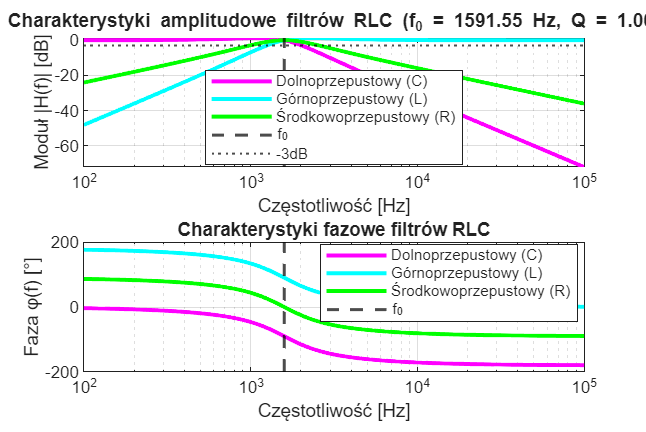


% Wizualizacja wszystkich filtrów
wykres_charakterystyki(w_czestotliwosci, wielkosc, faza, parametry, 'all');


% Opcjonalnie: wizualizacja pojedynczych filtrów
% wykres_charakterystyki(w_czestotliwosci, wielkosc, faza, parametry, 'LP');
% wykres_charakterystyki(w_czestotliwosci, wielkosc, faza, parametry, 'HP');
% wykres_charakterystyki(w_czestotliwosci, wielkosc, faza, parametry, 'BP');